clear; clc; close all;

% 1. อ่านไฟล์
filename = 'Waypoints_fix_doubleline.csv'; 
if exist(filename, 'file') ~= 2
    error(['หาไฟล์ ' filename ' ไม่เจอครับ!']);
end

opts = detectImportOptions(filename);
opts.VariableNamingRule = 'preserve'; % ป้องกันการเปลี่ยนชื่อคอลัมน์อัตโนมัติ
data = readtable(filename, opts);

% 2. ตรวจสอบชื่อคอลัมน์ (Case Sensitive)
disp('--- ชื่อคอลัมน์ที่อ่านได้ ---');

--- ชื่อคอลัมน์ที่อ่านได้ ---


disp(data.Properties.VariableNames);

    {'x'}    {'y'}    {'z'}    {'type'}    {'cmd'}    {'path_id'}    {'count'}




% พยายามดึงค่า x, y, z (รองรับตัวพิมพ์เล็ก/ใหญ่)
try
    % ใช้ฟังก์ชันช่วยหาชื่อคอลัมน์ที่ถูกต้อง
    x = data{:, strcmpi(data.Properties.VariableNames, 'x')};
    y = data{:, strcmpi(data.Properties.VariableNames, 'y')};
    z = data{:, strcmpi(data.Properties.VariableNames, 'z')};
catch
    error('หาคอลัมน์ x, y, z ไม่เจอ! ลองเช็คชื่อหัวตารางในไฟล์ CSV ครับ');
end

% 3. ตรวจสอบข้อมูลก่อนวาด
if isempty(x)
    error('อ่านไฟล์ได้ แต่ไม่มีข้อมูล (x ว่างเปล่า)');
end

% แสดงช่วงข้อมูล (Range) เพื่อดูว่าค่ามันเพี้ยนไหม
fprintf('Data Range:\n X: %.2f to %.2f\n Y: %.2f to %.2f\n Z: %.2f to %.2f\n', ...
    min(x), max(x), min(y), max(y), min(z), max(z));

Data Range:
 X: 0.25 to 0.75
 Y: -0.14 to 0.25
 Z: 0.00 to 0.05



if any(isnan(x)) || any(isnan(y)) || any(isnan(z))
    warning('แจ้งเตือน: มีค่า NaN ในข้อมูล กราฟอาจจะขาดหาย');
end

% 4. เริ่มวาด (Setup)
f = figure('Color', 'w', 'Name', 'Robot Path Debugger');
ax = gca;
grid(ax, 'on');
axis(ax, 'equal'); 
view(ax, 3);
hold(ax, 'on');
xlabel('X'); ylabel('Y'); zlabel('Z');

% ตั้งกล้องให้มองที่จุดแรก
if ~isnan(x(1))
    xlim([min(x) max(x)]);
    ylim([min(y) max(y)]);
    zlim([min(z) max(z)]);
end

hLine = animatedline('Color', 'b', 'LineWidth', 2);
hHead = plot3(nan, nan, nan, 'ro', 'MarkerFaceColor', 'r', 'MarkerSize', 8);

disp('Start Animation...');

Start Animation...


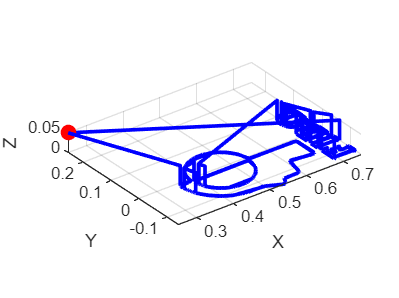


% 5. Loop วาด
for i = 1:length(x)
    if ~isvalid(hLine), break; end % กัน Error ถ้าปิดหน้าต่าง
    
    % วาดทีละจุด
    addpoints(hLine, x(i), y(i), z(i));
    set(hHead, 'XData', x(i), 'YData', y(i), 'ZData', z(i));
    
    % *** สำคัญ: ใช้ drawnow ธรรมดาเพื่อให้มั่นใจว่าวาดจริง (อาจช้าหน่อยแต่มองเห็นแน่) ***
    drawnow; 
end


disp('Done.');

Done.
